%% load images from cam1/ or cam0/, folder should contain single-ch tiff
dir = uigetdir("Title","Please select the Concrete Registration folder in your course files.");


%% read and sort files
imds = imageDatastore(dir, 'FileExtensions', {'.tif', '.tiff'}, 'IncludeSubfolders', false);

files = imds.Files;   % cell array of full paths

% Use \d+ or \d{1,3} to match 0..100 explicitly
tokens = regexp(files, '(?i)_([0-9]{1,3})_[GB]\.tiff?$', 'tokens', 'once');

nums = nan(size(tokens));
for k = 1:numel(tokens)
    if ~isempty(tokens{k})
        nums(k) = str2double(tokens{k}{1});
    end
end

% Sort by the numeric index (NaN go to end)
[~, order] = sort(nums, 'ascend', 'MissingPlacement', 'last');

% Reorder datastore (replace Files)
imds.Files = files(order);
numFiles = numel(imds.Files);

%% make a folder to save the masked_cropped_adapthisteq tiff
if contains(imds.Files{1}, 'cam0')
    saveDir = replace(dir, "/cam0", "/prepro_adapthisteq"); 
elseif contains(imds.Files{1},'cam1')
    saveDir = replace(dir, "/cam1", "/prepro_adapthisteq"); 
end
if ~isfolder(saveDir)
    mkdir(saveDir);
end

%% load camera-dependent mask
if contains(imds.Files{1}, 'cam0')
    cam_mask=load("cam0_mask.mat").square_mask;
    cam_mask =fliplr(cam_mask);
elseif contains(imds.Files{1},'cam1')
    cam_mask=load("cam1_mask.mat").square_mask;
end

%  compute the bounding box of the mask
%  [x, y, width, height]
props = regionprops(cam_mask, 'BoundingBox');
bb = ceil(props(1).BoundingBox);

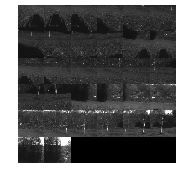

mask_cropped = cell(numFiles,1);
for i = 1:numFiles
    img = imread(imds.Files{i});
    % ensure img is same class as mask (logical indexing works for numeric types)
    img_masked = img;
    % img = fliplr(img); no need for img taken from feb 23 on
    img_masked(~cam_mask) = 0;
    %crop using bounding box bb [x, y, width, height]
    cropped = img_masked(bb(2):(bb(2)+bb(4)-1), bb(1):(bb(1)+bb(3)-1), :);
    mask_cropped{i} = cropped;
end
montage(mask_cropped)

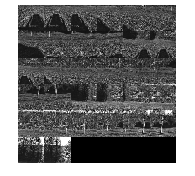

adapthisteq_ = cell(numFiles,1);
for i = 1:numFiles
    adapthisteq_{i}=adapthisteq(mask_cropped{i});
    if contains(imds.Files{1}, 'cam0')
        imwrite(adapthisteq_{i}, fullfile(saveDir, sprintf('prepro_adapthisteq_green_%d.tiff', i)));
    elseif contains(imds.Files{1}, 'cam1')
        imwrite(adapthisteq_{i}, fullfile(saveDir, sprintf('prepro_adapthisteq_uv_%d.tiff', i)));
    end
end
montage(adapthisteq_)